Here we give parameters for a Gaussian density. The parameter mu is the mean, and P is the covariance matrix.

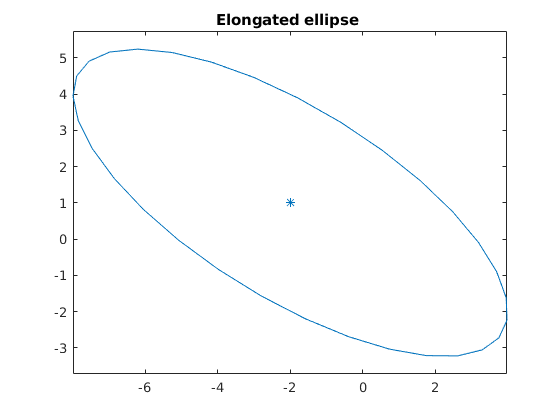

mu = [-2; 1];
P = [4, -2; -2 2];

%Call your function.
xy = sigmaEllipse2D(mu, P);

%Now plot the generated points. 
%You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure(1);
h1 = plot(xy(1,:), xy(2,:));

%Set the scale of x and y axis to be the same. 
% This should be done if the two variables are in the same domain,e.g. both are measured in meters.
axis equal
hold on
title("Elongated ellipse ")
%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu(1), mu(2), '*', 'color', h1.Color);
hold off

## **  Pretest**

- There should be two rows in the output (Pretest)

% randomize a 2D Gaussian distribution

mu = 5*randn(2,1);
s = 2*rand(2);
P = s'*s;
xy = sigmaEllipse2D(mu, P)

xy =     5.7940    6.0991    6.3151    6.4332    6.4485    6.3605    6.1727    5.8927    5.5322    5.1058    4.6310    4.1272    3.6151    3.1155    2.6491    2.2348    1.8897    1.6278    1.4599    1.3928    1.4294    1.5680    1.8031    2.1250    2.5205    2.9734    3.4653    3.9758    4.4843    4.9697    5.4124    5.7940
    3.2489    3.9130    4.4800    4.9268    5.2351    5.3922    5.3917    5.2337    4.9246    4.4770    3.9094    3.2448    2.5106    1.7368    0.9550    0.1974   -0.5052   -1.1239   -1.6335   -2.0130   -2.2469   -2.3256   -2.2459   -2.0112   -1.6309   -1.1206   -0.5014    0.2016    0.9595    1.7413    2.5150    3.2489



assert(size(xy,1) == 2, 'There should be two rows in the output');


       2. Assuming roughly equidistant points on the ellipse, is the mean of the ellipse correct? 

% randomize a 2D Gaussian distribution
mu = 5*randn(2,1);
s = 2*rand(2);
P = s'*s;

xy = sigmaEllipse2D(mu, P)

xy =    -5.0760   -4.8371   -4.7009   -4.6731   -4.7548   -4.9426   -5.2288   -5.6017   -6.0461   -6.5437   -7.0743   -7.6160   -8.1466   -8.6446   -9.0894   -9.4629   -9.7497   -9.9382  -10.0206   -9.9936   -9.8582   -9.6199   -9.2887   -8.8779   -8.4045   -7.8877   -7.3489   -6.8099   -6.2929   -5.8191   -5.4079   -5.0760
    2.3786    3.0615    3.6585    4.1449    4.5010    4.7122    4.7698    4.6715    4.4212    4.0293    3.5118    2.8898    2.1889    1.4377    0.6670   -0.0917   -0.8073   -1.4506   -1.9950   -2.4185   -2.7036   -2.8387   -2.8182   -2.6430   -2.3203   -1.8632   -1.2905   -0.6257    0.1041    0.8690    1.6377    2.3786



xy = unique(xy', 'rows')'

xy =   -10.0206   -9.9936   -9.9382   -9.8582   -9.7497   -9.6199   -9.4629   -9.2887   -9.0894   -8.8779   -8.6446   -8.4045   -8.1466   -7.8877   -7.6160   -7.3489   -7.0743   -6.8099   -6.5437   -6.2929   -6.0461   -5.8191   -5.6017   -5.4079   -5.2288   -5.0760   -5.0760   -4.9426   -4.8371   -4.7548   -4.7009   -4.6731
   -1.9950   -2.4185   -1.4506   -2.7036   -0.8073   -2.8387   -0.0917   -2.8182    0.6670   -2.6430    1.4377   -2.3203    2.1889   -1.8632    2.8898   -1.2905    3.5118   -0.6257    4.0293    0.1041    4.4212    0.8690    4.6715    1.6377    4.7698    2.3786    2.3786    4.7122    3.0615    4.5010    3.6585    4.1449



assert(all(abs(mean(xy, 2) - mu)./norm(mu) < 1e-1), ...
    'The mean of the ellipse points should roughly coincide with the distribution mean');


        3. Are the generated points on an ellipse of the right shape 

% randomize a 2D Gaussian distribution
mu = 5*randn(2,1);
s = 2*rand(2);
P = s'*s;
level = 1+rand*2;
npoints = 100+round(25*rand);

xy = sigmaEllipse2D(mu, P, level, npoints)

xy =     1.0305    1.1127    1.1872    1.2536    1.3119    1.3619    1.4033    1.4361    1.4601    1.4754    1.4817    1.4792    1.4678    1.4476    1.4187    1.3810    1.3348    1.2801    1.2172    1.1461    1.0673    0.9808    0.8870    0.7861    0.6784    0.5643    0.4441    0.3181    0.1869    0.0507   -0.0901   -0.2349   -0.3835   -0.5352   -0.6897   -0.8464   -1.0050   -1.1649   -1.3256   -1.4867   -1.6476   -1.8080   -1.9672   -2.1248   -2.2803   -2.4333   -2.5833   -2.7298   -2.8724   -3.0106
    3.3109    3.5194    3.7224    3.9195    4.1100    4.2933    4.4689    4.6362    4.7948    4.9441    5.0837    5.2132    5.3322    5.4403    5.5372    5.6226    5.6963    5.7579    5.8074    5.8446    5.8693    5.8815    5.8812    5.8683    5.8429    5.8051    5.7550    5.6927    5.6185    5.5325    5.4350    5.3263    5.2067    5.0767    4.9366    4.7868    4.6277    4.4599    4.2839    4.1002    3.9094    3.7120    3.5086    3.3000    3.0866    2.8691    2.6482    2.4247    2.1990    

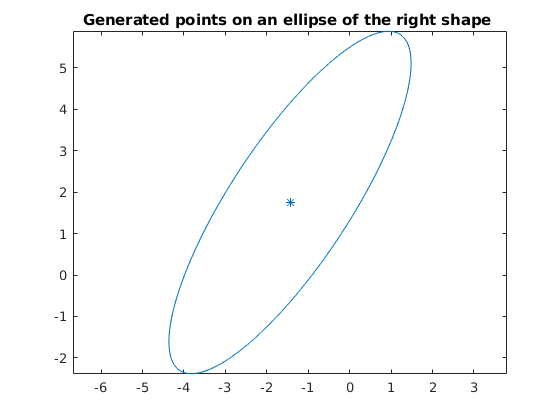


n = size(xy,2);
r2 = zeros(n,1);

for k = 1:n
    r2(k) = (xy(:,k)-mu)'/P*(xy(:,k)-mu);
end

mr2 = mean(r2);

assert(all(abs(r2-mr2) < 1e-5), 'The ellipse has the wrong shape') 

figure(1);
h1 = plot(xy(1,:), xy(2,:));
title("Generated points on an ellipse of the right shape ")
%Set the scale of x and y axis to be the same. 
% This should be done if the two variables are in the same domain,e.g. both are measured in meters.
axis equal
hold on

%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu(1), mu(2), '*', 'color', h1.Color);

hold off

 4.  Check that the level option is used to control the size of the ellipse.

% randomize a 2D Gaussian distribution
mu = 5*randn(2,1);
s = 2*rand(2);
P = s'*s;
level = 1+rand*2;

xy = sigmaEllipse2D(mu, P, level)

xy =    -2.8559   -2.7125   -2.6701   -2.7304   -2.8910   -3.1453   -3.4830   -3.8901   -4.3500   -4.8438   -5.3515   -5.8521   -6.3252   -6.7514   -7.1133   -7.3960   -7.5880   -7.6814   -7.6724   -7.5614   -7.3528   -7.0553   -6.6810   -6.2453   -5.7659   -5.2626   -4.7559   -4.2665   -3.8145   -3.4185   -3.0945   -2.8559
   10.3382   10.5139   10.6436   10.7219   10.7457   10.7139   10.6279   10.4912   10.3094   10.0899    9.8418    9.5751    9.3008    9.0301    8.7742    8.5434    8.3472    8.1938    8.0892    8.0379    8.0419    8.1011    8.2130    8.3731    8.5748    8.8098    9.0686    9.3405    9.6144    9.8790   10.1237   10.3382



n = size(xy,2);
r2 = zeros(n,1);
for k = 1:n
    r2(k) = (xy(:,k)-mu)'/P*(xy(:,k)-mu);
end

mr = sqrt(mean(r2))

mr = 1.0450

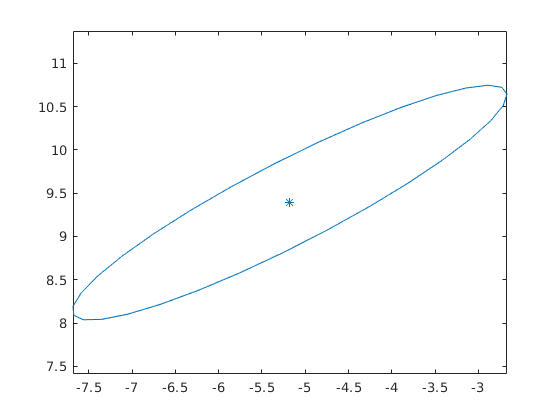


assert(abs(mr-level) < 1e-3, ['The ellipse has the wrong size.' ...
    'The third parameter should control the size of the ellipse.'])

figure(1);
h1 = plot(xy(1,:), xy(2,:));

%Set the scale of x and y axis to be the same. 
% This should be done if the two variables are in the same domain,e.g. both are measured in meters.
axis equal
hold on

%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu(1), mu(2), '*', 'color', h1.Color);
hold off

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, npoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Can take any positive value, 
%               but common choices are 1, 2 or 3. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          [2 x npoints] matrix. First row holds x-coordinates, second
%               row holds the y-coordinates. First and last columns should 
%               be the same point, to create a closed curve.


%Setting default values, in case only mu and Sigma are specified.
if nargin < 3
    level = 3;
end
if nargin < 4
    npoints = 32;
end

%Your code here

% linspace of theta range
angle_samples = linspace(0.0, 2* pi, npoints);

polar_tf = [cos(angle_samples); sin(angle_samples)];

%using equation (2)
xy = mu + level * (sqrtm(Sigma) * polar_tf);
end

